clear
clc

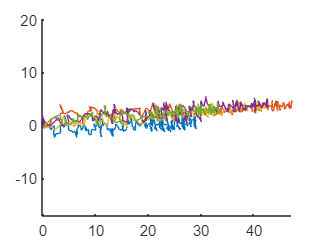

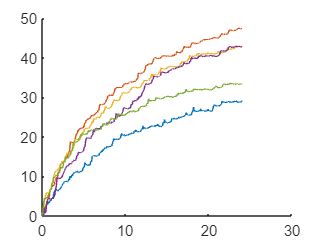

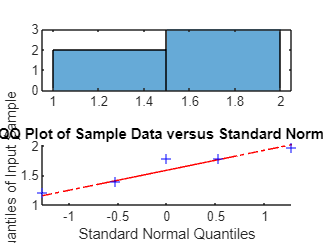

v_sand = 1.6273

std_sand = 0.3133

se_sand = 0.1401

s_sand = struct with fields:
    v_avg: [1.2137 1.9702 1.7811 1.7819 1.3896]


directory = 'data/three-surface-locomotion/sand/no-cycle';
[v_sand, std_sand, se_sand, s_sand] = forward_analysis(directory)

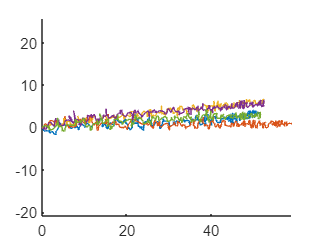

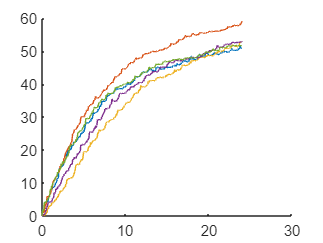

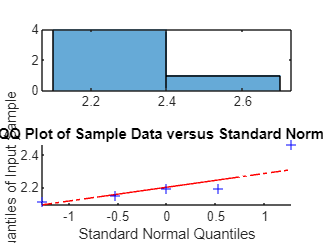

v_sand_05 = 2.2232

std_sand_05 = 0.1367

se_sand_05 = 0.0612

s_sand_05 = struct with fields:
    v_avg: [2.1158 2.4605 2.1948 2.1941 2.1505]



directory = 'data/three-surface-locomotion/sand/05Hz';
[v_sand_05, std_sand_05, se_sand_05, s_sand_05] = forward_analysis(directory)

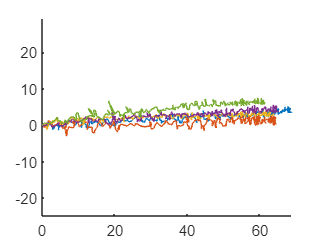

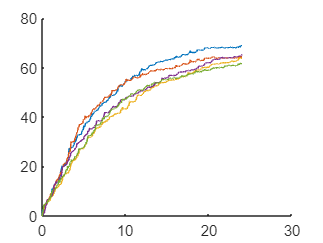

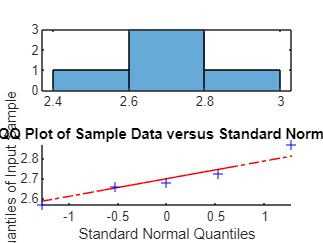

v_sand_09 = 2.6988

std_sand_09 = 0.1113

se_sand_09 = 0.0498

s_sand_09 = struct with fields:
    v_avg: [2.8691 2.6763 2.6575 2.7252 2.5661]



directory = 'data/three-surface-locomotion/sand/09Hz';
[v_sand_09, std_sand_09, se_sand_09, s_sand_09] = forward_analysis(directory)

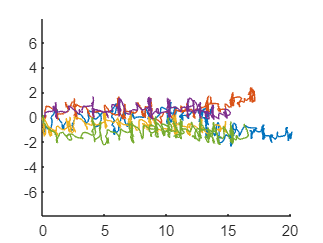

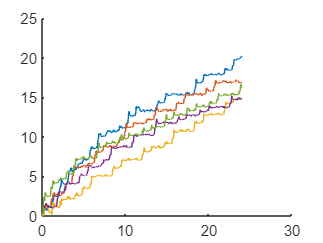

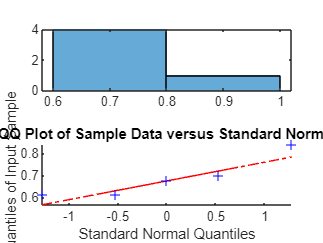

v_sand_load = 0.6893

std_sand_load = 0.0925

se_sand_load = 0.0414

s_sand_288 = struct with fields:
    v_avg: [0.8394 0.7007 0.6118 0.6154 0.6789]



directory = 'data/load-experiment/288g/sand/no-cycle';
[v_sand_load, std_sand_load, se_sand_load, s_sand_288] = forward_analysis(directory)

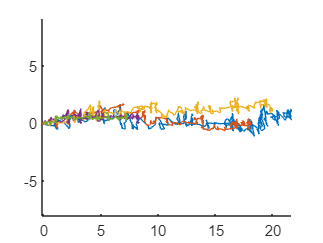

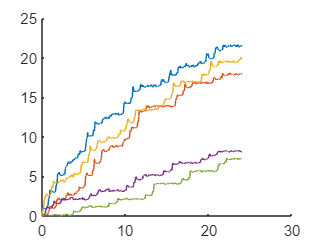

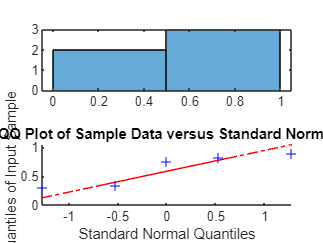

v_sand_05_load = 0.6202

std_sand_05_load = 0.2818

se_sand_05_load = 0.1260

s_sand_05_288 = struct with fields:
    v_avg: [0.8942 0.7484 0.8241 0.3369 0.2975]



directory = 'data/load-experiment/288g/sand/05Hz';
[v_sand_05_load, std_sand_05_load, se_sand_05_load, s_sand_05_288] = forward_analysis(directory)

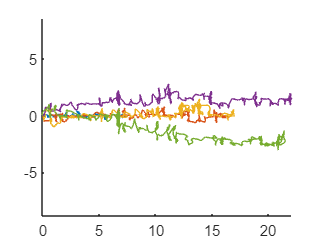

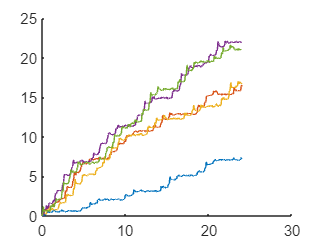

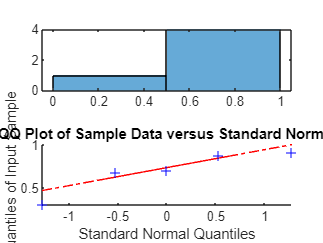

v_sand_09_load = 0.6920

std_sand_09_load = 0.2439

se_sand_09_load = 0.1091

s_sand_09_288 = struct with fields:
    v_avg: [0.2975 0.6798 0.6952 0.9126 0.8752]



directory = 'data/load-experiment/288g/sand/09Hz';
[v_sand_09_load, std_sand_09_load, se_sand_09_load, s_sand_09_288] = forward_analysis(directory)


s_sand_561 = struct('v_avg',[0 0 0 0 0]);
s_sand_05_561 = struct('v_avg',[0 0 0 0 0]);
s_sand_09_561 = struct('v_avg',[0 0 0 0 0]);

v_mean = [v_sand v_sand_05 v_sand_09
          v_sand_load v_sand_05_load v_sand_09_load];
v_std = [std_sand std_sand_05 std_sand_09
         std_sand_load std_sand_05_load std_sand_09_load];

b = figure;
figure(b);
hold on
bh = bar(v_mean);
bh(3).FaceColor = [0.4660 0.6740 0.1880];
set(gca, 'XTickLabel', {'No load' '288 g load'});
set(gca,'XTick',[1 2])
ylabel('Velocity [mm s$^{-1}$]','Interpreter','latex')

ngroups = size(v_mean, 1);
nbars = size(v_mean, 2);
% Calculating the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
for i = 1:nbars
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    er = errorbar(x, v_mean(:,i), v_std(:,i));
    er.Color = [0 0 0];
    er.LineStyle = 'none';
end
x0=10;
y0=10;
w=6.3;
height=5.85;
ylim([0 5])
set(gcf,'unit','centimeter','position',[x0,y0,w,height]);
lgnd = legend('No cycle', '0.5 Hz cycle', '0.9 Hz cycle','interpreter','latex')

lgnd =   Legend (No cycle, 0.5 Hz cycle, 0.9 Hz cycle) with properties:

         String: {'No cycle'  '0.5 Hz cycle'  '0.9 Hz cycle'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 8.1000
       Position: [0.4216 0.6873 0.4530 0.1980]
          Units: 'normalized'

  Show all properties


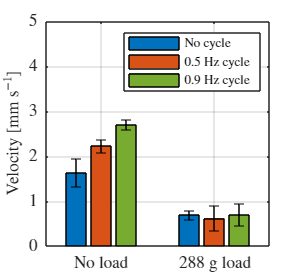

fontsize(10,'points')
fontsize(lgnd,8,'points')
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off

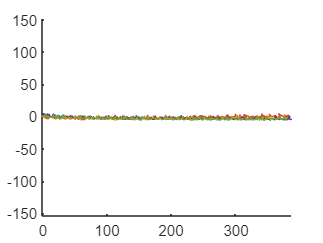

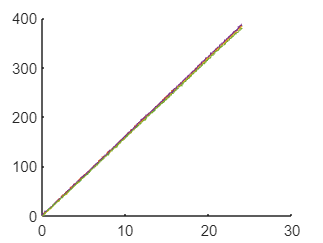

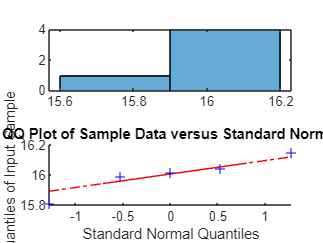

v_plywood = 15.9997

std_plywood = 0.1240

se_plywood = 0.0555

s_plywood = struct with fields:
    v_avg: [16.0417 16.0136 15.9854 16.1499 15.8079]


directory = 'data/three-surface-locomotion/plywood/no-cycle';
[v_plywood, std_plywood, se_plywood, s_plywood] = forward_analysis(directory)

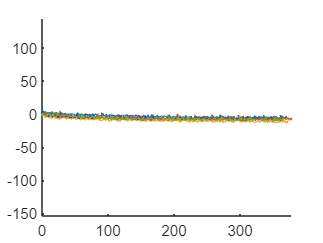

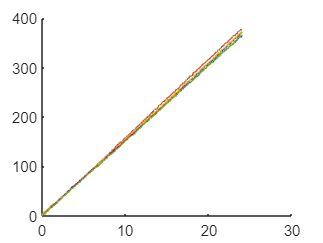

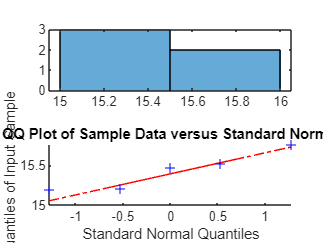

v_plywood_05 = 15.4298

std_plywood_05 = 0.2382

se_plywood_05 = 0.1065

s_plywood_05 = struct with fields:
    v_avg: [15.4740 15.7591 15.5211 15.2056 15.1891]



directory = 'data/three-surface-locomotion/plywood/05Hz';
[v_plywood_05, std_plywood_05, se_plywood_05, s_plywood_05] = forward_analysis(directory)

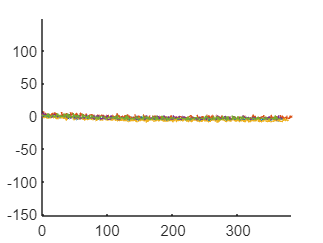

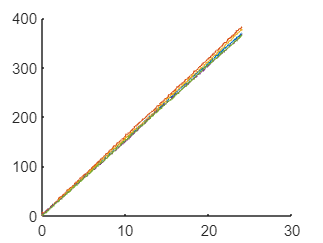

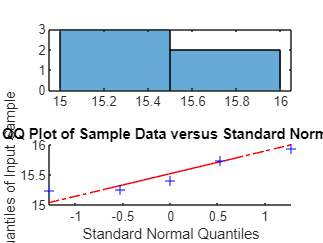

v_plywood_09 = 15.5159

std_plywood_09 = 0.3111

se_plywood_09 = 0.1391

s_plywood_09 = struct with fields:
    v_avg: [15.4056 15.9418 15.7376 15.2554 15.2392]



directory = 'data/three-surface-locomotion/plywood/09Hz';
[v_plywood_09, std_plywood_09, se_plywood_09, s_plywood_09] = forward_analysis(directory)

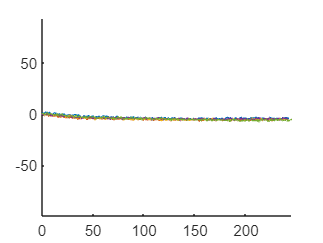

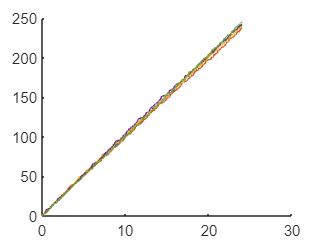

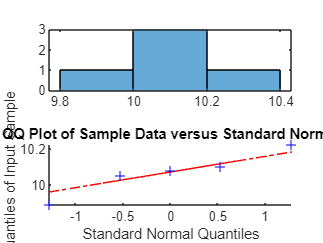

v_plywood_288 = 10.0679

std_plywood_288 = 0.1201

se_plywood_288 = 0.0537

s_plywood_288 = struct with fields:
    v_avg: [10.1025 9.8884 10.0773 10.0488 10.2222]



directory = 'data/load-experiment/288g/plywood/no-cycle';
[v_plywood_288, std_plywood_288, se_plywood_288, s_plywood_288] = forward_analysis(directory)

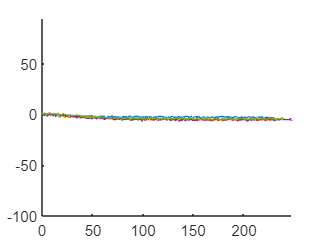

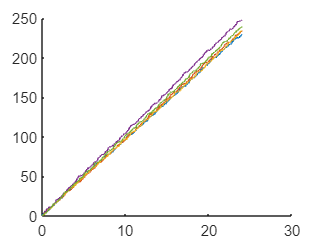

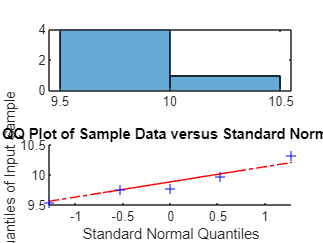

v_plywood_05_288 = 9.8706

std_plywood_05_288 = 0.2942

se_plywood_05_288 = 0.1316

s_plywood_05_288 = struct with fields:
    v_avg: [9.5392 9.7630 9.7564 10.3184 9.9761]



directory = 'data/load-experiment/288g/plywood/05Hz';
[v_plywood_05_288, std_plywood_05_288, se_plywood_05_288, s_plywood_05_288] = forward_analysis(directory)

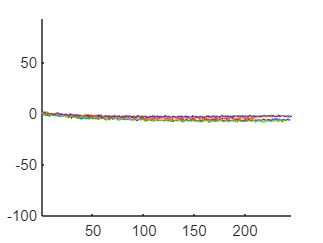

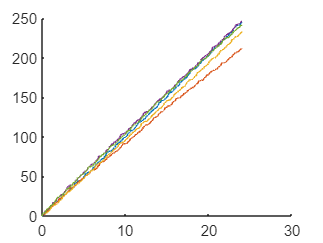

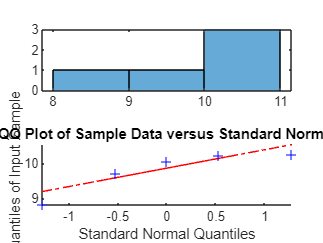

v_plywood_09_288 = 9.8080

std_plywood_09_288 = 0.5972

se_plywood_09_288 = 0.2671

s_plywood_09_288 = struct with fields:
    v_avg: [10.2179 8.8122 9.7073 10.2539 10.0488]



directory = 'data/load-experiment/288g/plywood/09Hz';
[v_plywood_09_288, std_plywood_09_288, se_plywood_09_288, s_plywood_09_288] = forward_analysis(directory)

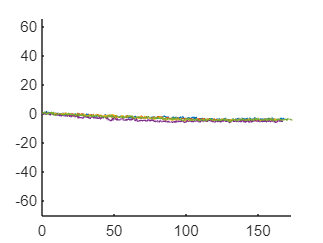

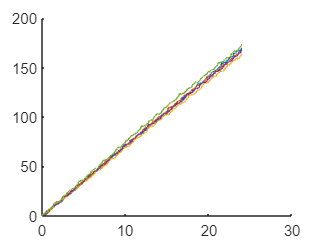

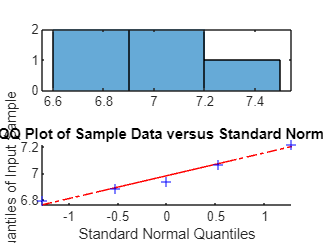

v_plywood_561 = 6.9800

std_plywood_561 = 0.1660

se_plywood_561 = 0.0742

s_plywood_561 = struct with fields:
    v_avg: [7.0684 6.8833 6.7920 6.9393 7.2168]



directory = 'data/load-experiment/561g/plywood/no-cycle';
[v_plywood_561, std_plywood_561, se_plywood_561, s_plywood_561] = forward_analysis(directory)

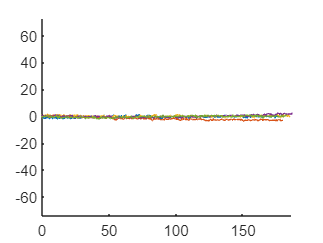

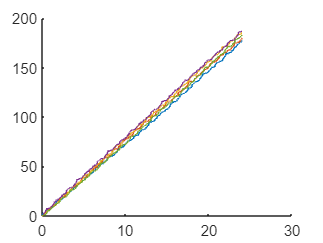

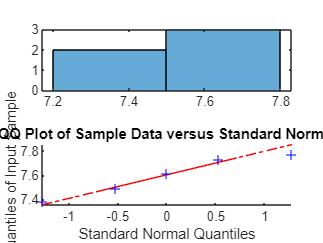

v_plywood_05_561 = 7.5981

std_plywood_05_561 = 0.1617

se_plywood_05_561 = 0.0723

s_plywood_05_561 = struct with fields:
    v_avg: [7.3847 7.4924 7.7299 7.7720 7.6114]



directory = 'data/load-experiment/561g/plywood/05Hz';
[v_plywood_05_561, std_plywood_05_561, se_plywood_05_561, s_plywood_05_561] = forward_analysis(directory)

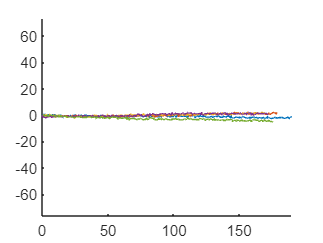

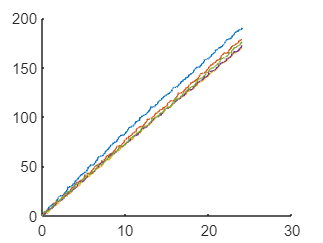

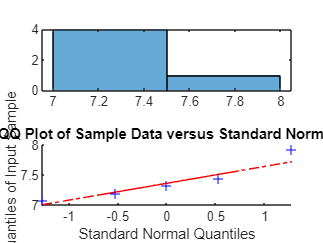

v_plywood_09_561 = 7.3895

std_plywood_09_561 = 0.3255

se_plywood_09_561 = 0.1456

s_plywood_09_561 = struct with fields:
    v_avg: [7.9189 7.4371 7.0804 7.1860 7.3251]



directory = 'data/load-experiment/561g/plywood/09Hz';
[v_plywood_09_561, std_plywood_09_561, se_plywood_09_561, s_plywood_09_561] = forward_analysis(directory)

v_mean = [v_plywood v_plywood_05 v_plywood_09
          v_plywood_288 v_plywood_05_288 v_plywood_09_288
          v_plywood_561 v_plywood_05_561 v_plywood_09_561];
v_std = [std_plywood std_plywood_05 std_plywood_09
         std_plywood_288 std_plywood_05_288 std_plywood_09_288
         std_plywood_561 std_plywood_05_561 std_plywood_09_561];

b = figure;
figure(b);
hold on
bh = bar(v_mean);
bh(3).FaceColor = [0.4660 0.6740 0.1880];
set(gca, 'XTickLabel', {'No load' '288 g load' '561 g load'});
set(gca,'XTick',[1 2 3])
ylabel('Velocity [mm s$^{-1}$]','Interpreter','latex')

ngroups = size(v_mean, 1);
nbars = size(v_mean, 2);
% Calculating the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
for i = 1:nbars
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    er = errorbar(x, v_mean(:,i), v_std(:,i));
    er.Color = [0 0 0];
    er.LineStyle = 'none';
end
x0=10;
y0=10;
w=6.3;
height=5.85;
%ylim([0 5])
set(gcf,'unit','centimeter','position',[x0,y0,w,height]);
lgnd = legend('No cycle', '0.5 Hz cycle', '0.9 Hz cycle','interpreter','latex')

lgnd =   Legend (No cycle, 0.5 Hz cycle, 0.9 Hz cycle) with properties:

         String: {'No cycle'  '0.5 Hz cycle'  '0.9 Hz cycle'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 8.1000
       Position: [0.4216 0.6873 0.4530 0.1980]
          Units: 'normalized'

  Show all properties


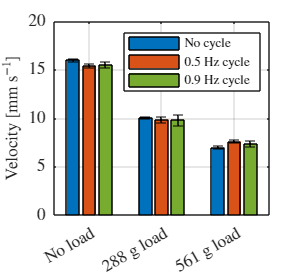

fontsize(10,'points')
fontsize(lgnd,8,'points')
set(gca,'TickLabelInterpreter','latex')
grid on
box on
hold off

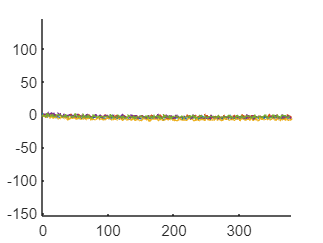

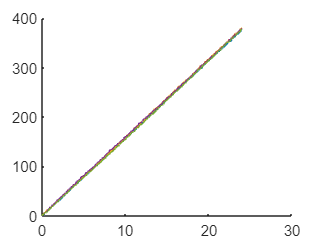

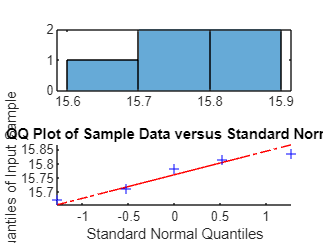

v_pmma = 15.7635

std_pmma = 0.0686

se_pmma = 0.0307

s_pmma = struct with fields:
    v_avg: [15.6742 15.8152 15.8345 15.7823 15.7110]


directory = 'data/three-surface-locomotion/pmma/no-cycle';
[v_pmma, std_pmma, se_pmma, s_pmma] = forward_analysis(directory)

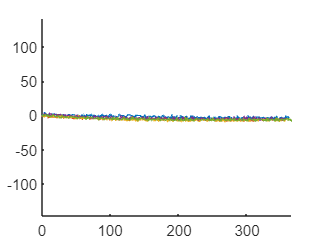

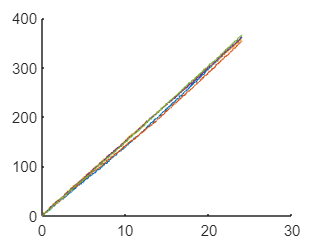

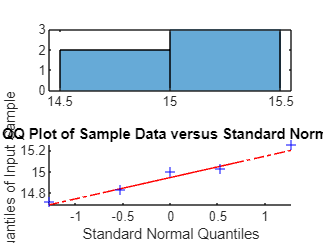

v_pmma_05 = 14.9667

std_pmma_05 = 0.2059

se_pmma_05 = 0.0921

s_pmma_05 = struct with fields:
    v_avg: [15.0320 14.7151 14.8299 15.0034 15.2531]



directory = 'data/three-surface-locomotion/pmma/05Hz';
[v_pmma_05, std_pmma_05, se_pmma_05, s_pmma_05] = forward_analysis(directory)

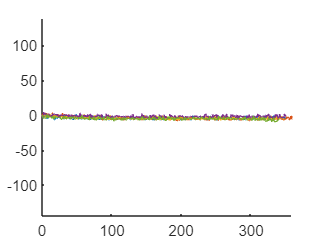

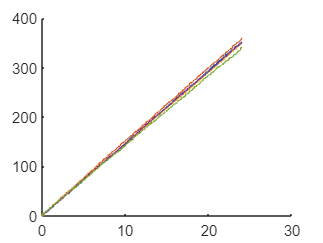

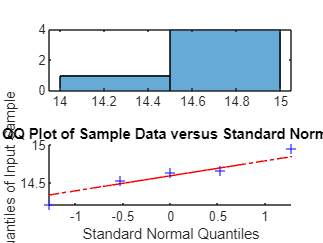

v_pmma_09 = 14.5992

std_pmma_09 = 0.2665

se_pmma_09 = 0.1192

s_pmma_09 = struct with fields:
    v_avg: [14.6587 14.9530 14.5326 14.6394 14.2126]



directory = 'data/three-surface-locomotion/pmma/09Hz';
[v_pmma_09, std_pmma_09, se_pmma_09, s_pmma_09] = forward_analysis(directory)

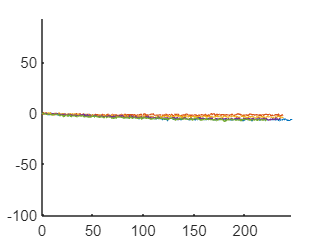

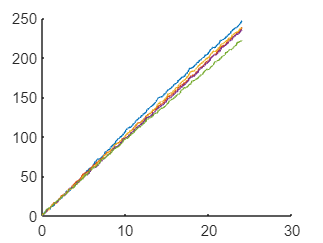

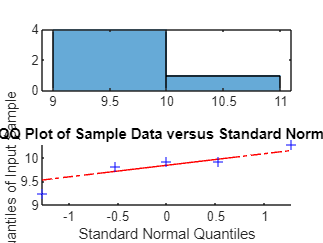

v_pmma_288 = 9.8353

std_pmma_288 = 0.3781

se_pmma_288 = 0.1691

s_pmma_288 = struct with fields:
    v_avg: [10.2795 9.9288 9.9220 9.8087 9.2374]



directory = 'data/load-experiment/288g/pmma/no-cycle';
[v_pmma_288, std_pmma_288, se_pmma_288, s_pmma_288] = forward_analysis(directory)

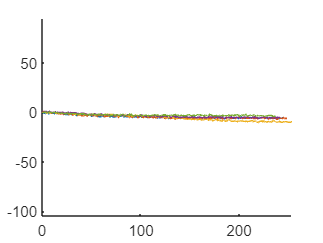

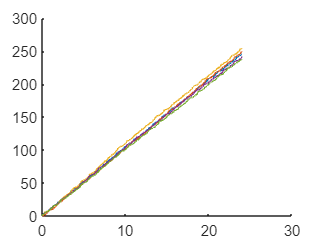

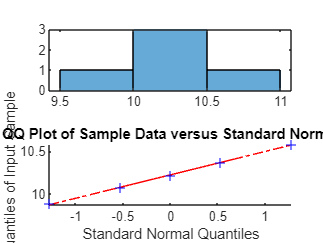

v_pmma_05_288 = 10.2220

std_pmma_05_288 = 0.2681

se_pmma_05_288 = 0.1199

s_pmma_05_288 = struct with fields:
    v_avg: [10.2105 10.3664 10.5798 10.0717 9.8814]



directory = 'data/load-experiment/288g/pmma/05Hz';
[v_pmma_05_288, std_pmma_05_288, se_pmma_05_288, s_pmma_05_288] = forward_analysis(directory)

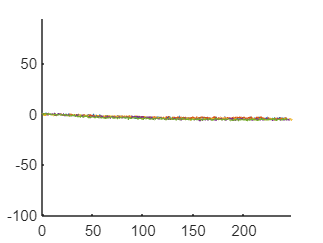

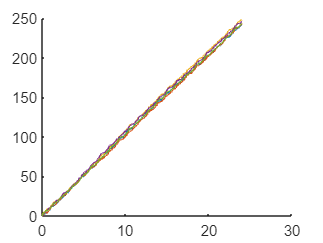

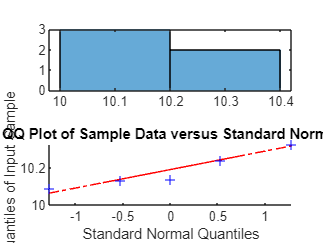

v_pmma_09_288 = 10.1828

std_pmma_09_288 = 0.0966

se_pmma_09_288 = 0.0432

s_pmma_09_288 = struct with fields:
    v_avg: [10.0871 10.1294 10.3235 10.2394 10.1345]



directory = 'data/load-experiment/288g/pmma/09Hz';
[v_pmma_09_288, std_pmma_09_288, se_pmma_09_288, s_pmma_09_288] = forward_analysis(directory)

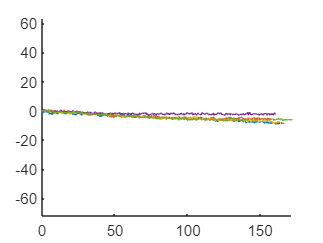

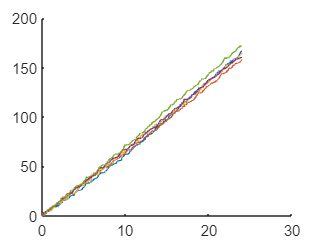

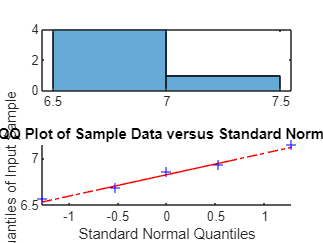

v_pmma_561 = 6.8383

std_pmma_561 = 0.2217

se_pmma_561 = 0.0991

s_pmma_561 = struct with fields:
    v_avg: [6.9332 6.5701 6.8559 6.6891 7.1434]



directory = 'data/load-experiment/561g/pmma/no-cycle';
[v_pmma_561, std_pmma_561, se_pmma_561, s_pmma_561] = forward_analysis(directory)

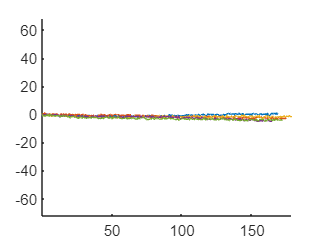

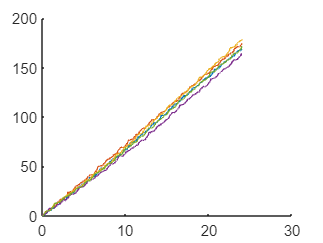

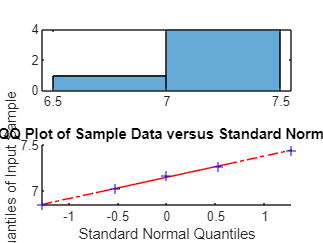

v_pmma_05_561 = 7.1499

std_pmma_05_561 = 0.2259

se_pmma_05_561 = 0.1010

s_pmma_05_561 = struct with fields:
    v_avg: [7.0281 7.2684 7.4396 6.8482 7.1652]



directory = 'data/load-experiment/561g/pmma/05Hz';
[v_pmma_05_561, std_pmma_05_561, se_pmma_05_561, s_pmma_05_561] = forward_analysis(directory)

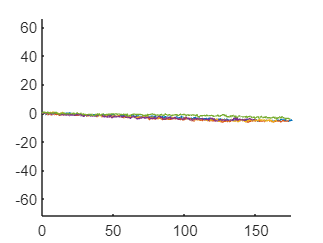

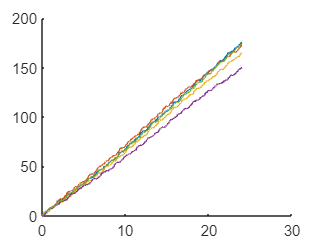

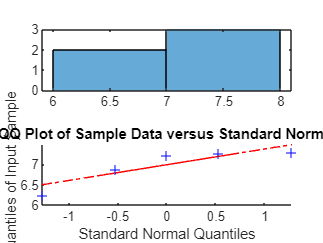

v_pmma_09_561 = 6.9801

std_pmma_09_561 = 0.4457

se_pmma_09_561 = 0.1993

s_pmma_09_561 = struct with fields:
    v_avg: [7.3058 7.2175 6.8749 6.2430 7.2591]



directory = 'data/load-experiment/561g/pmma/09Hz';
[v_pmma_09_561, std_pmma_09_561, se_pmma_09_561, s_pmma_09_561] = forward_analysis(directory)

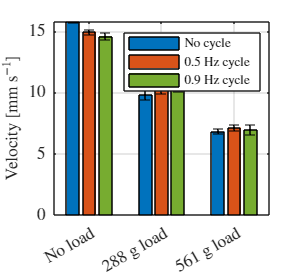

v_mean = [v_pmma v_pmma_05 v_pmma_09
          v_pmma_288 v_pmma_05_288 v_pmma_09_288
          v_pmma_561 v_pmma_05_561 v_pmma_09_561];

v_std = [std_pmma std_pmma_05 std_pmma_09
         std_pmma_288 std_pmma_05_288 std_pmma_09_288
         std_pmma_561 std_pmma_05_561 std_pmma_09_561];

b = figure;
figure(b);
hold on
bh = bar(v_mean);
bh(3).FaceColor = [0.4660 0.6740 0.1880];
set(gca, 'XTickLabel', {'No load' '288 g load' '561 g load'});
set(gca,'XTick',[1 2 3])
ylabel('Velocity [mm s$^{-1}$]','Interpreter','latex')

ngroups = size(v_mean, 1);
nbars = size(v_mean, 2);
groupwidth = min(0.8, nbars/(nbars + 1.5));
for i = 1:nbars
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    er = errorbar(x, v_mean(:,i), v_std(:,i));
    er.Color = [0 0 0];
    er.LineStyle = 'none';
end
x0=10;
y0=10;
w=6.3;
height=5.85;
set(gcf,'unit','centimeter','position',[x0,y0,w,height]);
lgnd = legend('No cycle', '0.5 Hz cycle', '0.9 Hz cycle','interpreter','latex');
fontsize(10,'points');
fontsize(lgnd,8,'points');
set(gca,'TickLabelInterpreter','latex');
grid on;
box on;
hold off;

% Define the corrected cycles and suffix mapping
cycle_labels = {'none', '0.5Hz', '0.9Hz'};
cycle_suffixes = {'', '_05', '_09'};

load_labels = {'none', '288g', '561g'};
load_suffixes = {'', '_288', '_561'};

surfaces = {'plywood', 'pmma', 'sand'};

% Initialize storage
Velocity = [];
Surface = {};
Load = {};
Cycle = {};

for i = 1:length(surfaces)
    surf = surfaces{i};
    for j = 1:length(load_labels)
        load_label = load_labels{j};
        load_sfx = load_suffixes{j};
        for k = 1:length(cycle_labels)
            cycle_label = cycle_labels{k};
            cycle_sfx = cycle_suffixes{k};

            % Construct variable name
            if strcmp(load_label, 'none') && strcmp(cycle_label, 'none')
                varname = ['s_' surf];
            elseif strcmp(load_label, 'none')
                varname = ['s_' surf cycle_sfx];
            elseif strcmp(cycle_label, 'none')
                varname = ['s_' surf load_sfx];
            else
                varname = ['s_' surf cycle_sfx load_sfx];
            end

            % Pull data from base workspace
            if evalin('base', ['exist(''' varname ''', ''var'')'])
                s_struct = evalin('base', varname);
                v_data = s_struct.v_avg(:);

                % Append
                Velocity = [Velocity; v_data];
                Surface = [Surface; repmat({surf}, length(v_data), 1)];
                Load = [Load; repmat({load_label}, length(v_data), 1)];
                Cycle = [Cycle; repmat({cycle_label}, length(v_data), 1)];
            else
                warning(['Missing variable: ' varname]);
            end
        end
    end
end

% Build table
T = table(categorical(Surface), categorical(Load), categorical(Cycle), Velocity, ...
    'VariableNames', {'Surface', 'Load', 'Cycle', 'Velocity'});

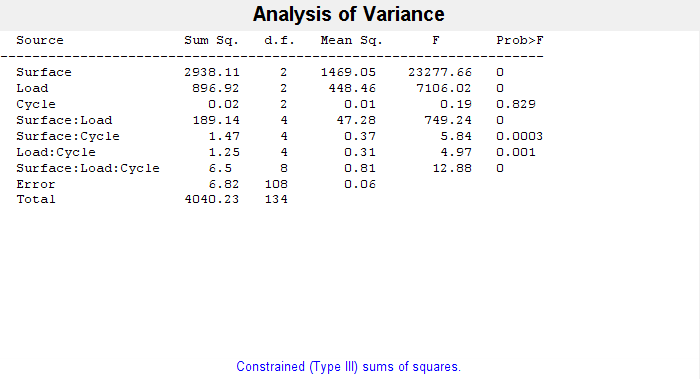

T.Surface = categorical(T.Surface);
T.Load = categorical(T.Load);
T.Cycle = categorical(T.Cycle);

[p, tbl, stats] = anovan(T.Velocity, {T.Surface, T.Load, T.Cycle}, ...
    'model', 'full', ...
    'varnames', {'Surface', 'Load', 'Cycle'});


Analyzing Surface effect at Load = none and Cycle = none


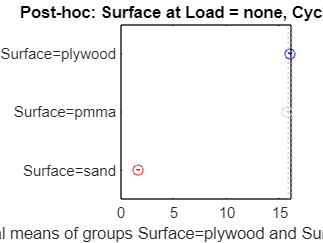

Surface=plywood differs from Surface=pmma (p = 0.253)
Surface=plywood differs from Surface=sand (p = 0.000)
Surface=pmma differs from Surface=sand (p = 0.000)



Analyzing Surface effect at Load = none and Cycle = 0.5Hz


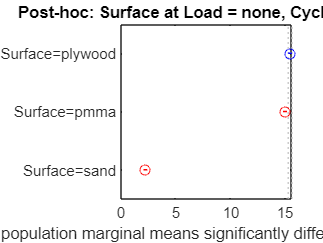

Surface=plywood differs from Surface=pmma (p = 0.009)
Surface=plywood differs from Surface=sand (p = 0.000)
Surface=pmma differs from Surface=sand (p = 0.000)



Analyzing Surface effect at Load = none and Cycle = 0.9Hz


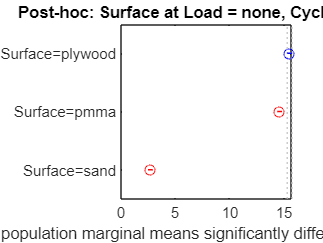

Surface=plywood differs from Surface=pmma (p = 0.000)
Surface=plywood differs from Surface=sand (p = 0.000)
Surface=pmma differs from Surface=sand (p = 0.000)



Analyzing Surface effect at Load = 288g and Cycle = none


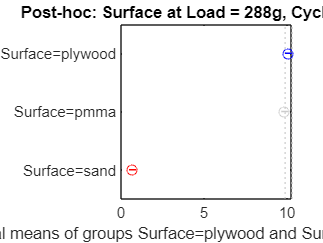

Surface=plywood differs from Surface=pmma (p = 0.432)
Surface=plywood differs from Surface=sand (p = 0.000)
Surface=pmma differs from Surface=sand (p = 0.000)



Analyzing Surface effect at Load = 288g and Cycle = 0.5Hz


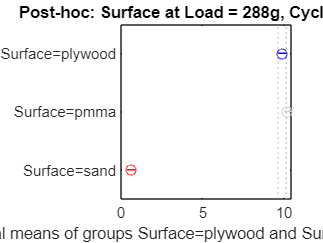

Surface=plywood differs from Surface=pmma (p = 0.216)
Surface=plywood differs from Surface=sand (p = 0.000)
Surface=pmma differs from Surface=sand (p = 0.000)



Analyzing Surface effect at Load = 288g and Cycle = 0.9Hz


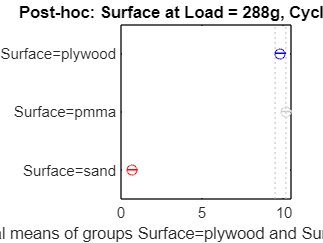

Surface=plywood differs from Surface=pmma (p = 0.425)
Surface=plywood differs from Surface=sand (p = 0.000)
Surface=pmma differs from Surface=sand (p = 0.000)



Analyzing Surface effect at Load = 561g and Cycle = none


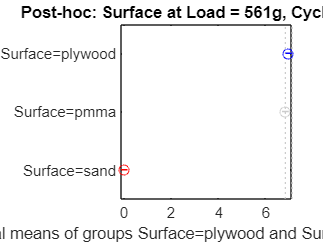

Surface=plywood differs from Surface=pmma (p = 0.560)
Surface=plywood differs from Surface=sand (p = 0.000)
Surface=pmma differs from Surface=sand (p = 0.000)



Analyzing Surface effect at Load = 561g and Cycle = 0.5Hz


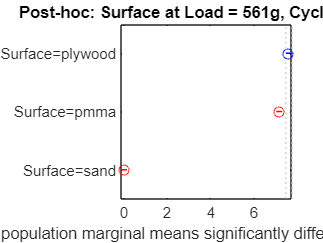

Surface=plywood differs from Surface=pmma (p = 0.003)
Surface=plywood differs from Surface=sand (p = 0.000)
Surface=pmma differs from Surface=sand (p = 0.000)



Analyzing Surface effect at Load = 561g and Cycle = 0.9Hz


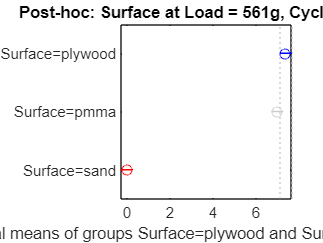

Surface=plywood differs from Surface=pmma (p = 0.195)
Surface=plywood differs from Surface=sand (p = 0.000)
Surface=pmma differs from Surface=sand (p = 0.000)


% Define labels
cycle_labels = {'none', '0.5Hz', '0.9Hz'};
load_labels = {'none', '288g', '561g'};
surfaces = {'plywood', 'pmma', 'sand'};

% Loop through all combinations of Load and Cycle
for i = 1:length(load_labels)
    for j = 1:length(cycle_labels)

        % Subset the data
        subset = T(T.Load == load_labels{i} & T.Cycle == cycle_labels{j}, :);

        % Check that subset is not empty and has more than one surface
        if height(subset) > 1 && numel(unique(subset.Surface)) > 1

            % Run one-way ANOVA for Surface within this Load × Cycle
            fprintf('\nAnalyzing Surface effect at Load = %s and Cycle = %s\n', ...
                load_labels{i}, cycle_labels{j});
            [p, tbl, stats] = anovan(subset.Velocity, {subset.Surface}, ...
                'varnames', {'Surface'}, 'display', 'off');

            % Perform post hoc test
            figure;
            [c, m, h, gnames] = multcompare(stats, 'CriticalValueType', 'bonferroni');
            title(sprintf('Post-hoc: Surface at Load = %s, Cycle = %s', ...
                load_labels{i}, cycle_labels{j}));

            % Print significant differences
            %idx = find(c(:,6) < 0.05);
            for k = 1:length(c(:,6))
                g1 = gnames{c(k,1)};
                g2 = gnames{c(k,2)};
                fprintf('%s differs from %s (p = %.3f)\n', g1, g2, c(k,6));
            end
        else
            fprintf('Skipping condition Load = %s, Cycle = %s (insufficient data)\n', ...
                load_labels{i}, cycle_labels{j});
        end
    end
end


Analyzing Load effect at Surface = plywood and Cycle = none


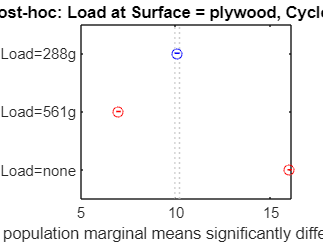

Load=288g differs from Load=561g (p = 0.000)
Load=288g differs from Load=none (p = 0.000)
Load=561g differs from Load=none (p = 0.000)



Analyzing Load effect at Surface = plywood and Cycle = 0.5Hz


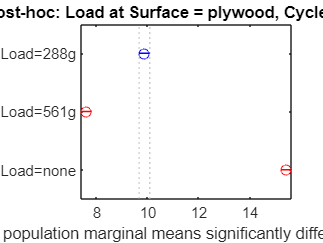

Load=288g differs from Load=561g (p = 0.000)
Load=288g differs from Load=none (p = 0.000)
Load=561g differs from Load=none (p = 0.000)



Analyzing Load effect at Surface = plywood and Cycle = 0.9Hz


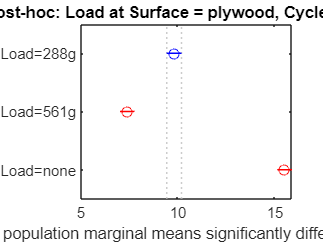

Load=288g differs from Load=561g (p = 0.000)
Load=288g differs from Load=none (p = 0.000)
Load=561g differs from Load=none (p = 0.000)



Analyzing Load effect at Surface = pmma and Cycle = none


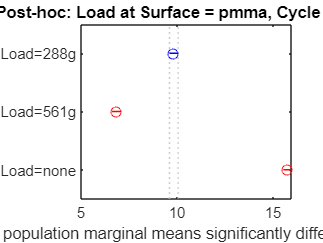

Load=288g differs from Load=561g (p = 0.000)
Load=288g differs from Load=none (p = 0.000)
Load=561g differs from Load=none (p = 0.000)



Analyzing Load effect at Surface = pmma and Cycle = 0.5Hz


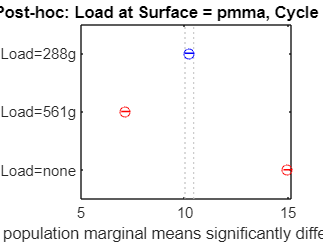

Load=288g differs from Load=561g (p = 0.000)
Load=288g differs from Load=none (p = 0.000)
Load=561g differs from Load=none (p = 0.000)



Analyzing Load effect at Surface = pmma and Cycle = 0.9Hz


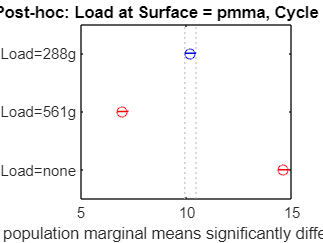

Load=288g differs from Load=561g (p = 0.000)
Load=288g differs from Load=none (p = 0.000)
Load=561g differs from Load=none (p = 0.000)



Analyzing Load effect at Surface = sand and Cycle = none


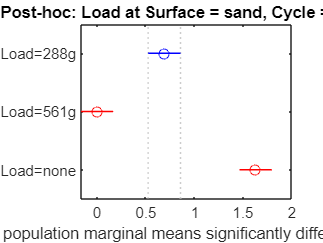

Load=288g differs from Load=561g (p = 0.000)
Load=288g differs from Load=none (p = 0.000)
Load=561g differs from Load=none (p = 0.000)



Analyzing Load effect at Surface = sand and Cycle = 0.5Hz


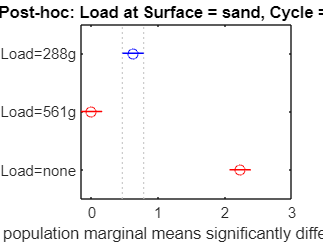

Load=288g differs from Load=561g (p = 0.000)
Load=288g differs from Load=none (p = 0.000)
Load=561g differs from Load=none (p = 0.000)



Analyzing Load effect at Surface = sand and Cycle = 0.9Hz


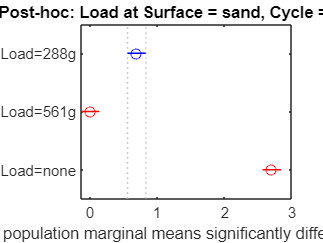

Load=288g differs from Load=561g (p = 0.000)
Load=288g differs from Load=none (p = 0.000)
Load=561g differs from Load=none (p = 0.000)


% Loop through Surface and Cycle to analyze Load effects
for i = 1:length(surfaces)
    for j = 1:length(cycle_labels)

        % Subset data
        subset = T((T.Surface == surfaces{i}) & (T.Cycle == cycle_labels{j}), :);

        % Check there's enough data to run ANOVA
        if height(subset) > 1 && numel(unique(subset.Load)) > 1

            fprintf('\nAnalyzing Load effect at Surface = %s and Cycle = %s\n', ...
                surfaces{i}, cycle_labels{j});
            [p, tbl, stats] = anovan(subset.Velocity, {subset.Load}, ...
                'varnames', {'Load'}, 'display', 'off');

            % Bonferroni post hoc
            figure;
            [c, m, h, gnames] = multcompare(stats, 'CriticalValueType', 'bonferroni');
            title(sprintf('Post-hoc: Load at Surface = %s, Cycle = %s', ...
                surfaces{i}, cycle_labels{j}));

            % Print significant differences
            idx = find(c(:,6) < 0.05);
            for k = 1:length(idx)
                g1 = gnames{c(idx(k),1)};
                g2 = gnames{c(idx(k),2)};
                fprintf('%s differs from %s (p = %.3f)\n', g1, g2, c(idx(k),6));
            end
        else
            fprintf('Skipping Surface = %s, Cycle = %s (insufficient data)\n', ...
                surfaces{i}, cycle_labels{j});
        end
    end
end


Analyzing Cycle effect at Surface = plywood and Load = none


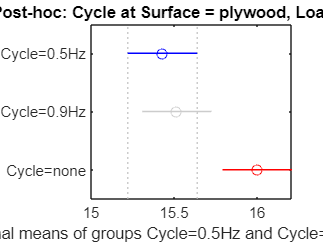

Cycle=0.5Hz differs from Cycle=0.9Hz (p = 1.000)
Cycle=0.5Hz differs from Cycle=none (p = 0.008)
Cycle=0.9Hz differs from Cycle=none (p = 0.022)



Analyzing Cycle effect at Surface = plywood and Load = 288g


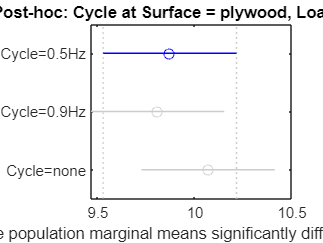

Cycle=0.5Hz differs from Cycle=0.9Hz (p = 1.000)
Cycle=0.5Hz differs from Cycle=none (p = 1.000)
Cycle=0.9Hz differs from Cycle=none (p = 0.941)



Analyzing Cycle effect at Surface = plywood and Load = 561g


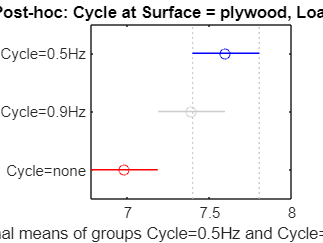

Cycle=0.5Hz differs from Cycle=0.9Hz (p = 0.535)
Cycle=0.5Hz differs from Cycle=none (p = 0.003)
Cycle=0.9Hz differs from Cycle=none (p = 0.047)



Analyzing Cycle effect at Surface = pmma and Load = none


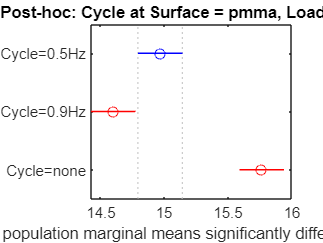

Cycle=0.5Hz differs from Cycle=0.9Hz (p = 0.038)
Cycle=0.5Hz differs from Cycle=none (p = 0.000)
Cycle=0.9Hz differs from Cycle=none (p = 0.000)



Analyzing Cycle effect at Surface = pmma and Load = 288g


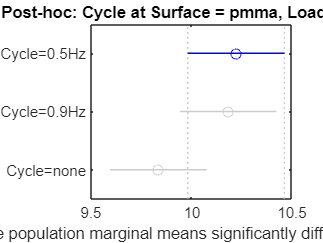

Cycle=0.5Hz differs from Cycle=0.9Hz (p = 1.000)
Cycle=0.5Hz differs from Cycle=none (p = 0.135)
Cycle=0.9Hz differs from Cycle=none (p = 0.202)



Analyzing Cycle effect at Surface = pmma and Load = 561g


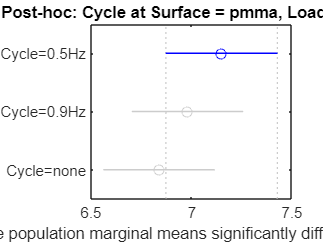

Cycle=0.5Hz differs from Cycle=0.9Hz (p = 1.000)
Cycle=0.5Hz differs from Cycle=none (p = 0.434)
Cycle=0.9Hz differs from Cycle=none (p = 1.000)



Analyzing Cycle effect at Surface = sand and Load = none


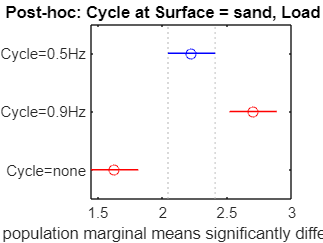

Cycle=0.5Hz differs from Cycle=0.9Hz (p = 0.010)
Cycle=0.5Hz differs from Cycle=none (p = 0.002)
Cycle=0.9Hz differs from Cycle=none (p = 0.000)



Analyzing Cycle effect at Surface = sand and Load = 288g


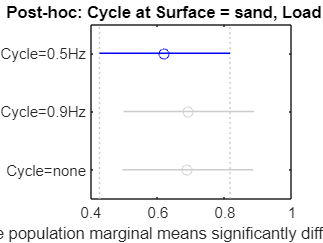

Cycle=0.5Hz differs from Cycle=0.9Hz (p = 1.000)
Cycle=0.5Hz differs from Cycle=none (p = 1.000)
Cycle=0.9Hz differs from Cycle=none (p = 1.000)



Analyzing Cycle effect at Surface = sand and Load = 561g


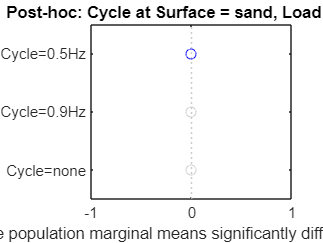

Cycle=0.5Hz differs from Cycle=0.9Hz (p = NaN)
Cycle=0.5Hz differs from Cycle=none (p = NaN)
Cycle=0.9Hz differs from Cycle=none (p = NaN)


% Loop through Surface and Load to analyze Cycle effects
for i = 1:length(surfaces)
    for j = 1:length(load_labels)

        % Subset data
        subset = T(T.Surface == surfaces{i} & T.Load == load_labels{j}, :);

        % Check there's enough data to run ANOVA
        if height(subset) > 1 && numel(unique(subset.Cycle)) > 1

            fprintf('\nAnalyzing Cycle effect at Surface = %s and Load = %s\n', ...
                surfaces{i}, load_labels{j});
            [p, tbl, stats] = anovan(subset.Velocity, {subset.Cycle}, ...
                'varnames', {'Cycle'}, 'display', 'off');

            % Bonferroni post hoc
            figure;
            [c, m, h, gnames] = multcompare(stats, 'CriticalValueType', 'bonferroni');
            title(sprintf('Post-hoc: Cycle at Surface = %s, Load = %s', ...
                surfaces{i}, load_labels{j}));

            % Print significant differences
            idx = find(c(:,6));
            for k = 1:length(idx)
                g1 = gnames{c(idx(k),1)};
                g2 = gnames{c(idx(k),2)};
                fprintf('%s differs from %s (p = %.3f)\n', g1, g2, c(idx(k),6));
            end
        else
            fprintf('Skipping Surface = %s, Load = %s (insufficient data)\n', ...
                surfaces{i}, load_labels{j});
        end
    end
end